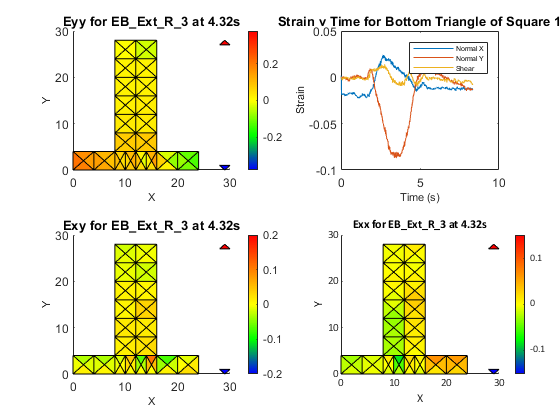

Error using load
Unable to read MAT-file C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Biomechanics MATLAB Subjects 1-30\Subject 2\EB_Flex_1.mat. Not a binary MAT-file. Try load -ASCII to read as text.

Error in StrainAnalysis (line 26)
input=load(name{1},name{2});

sn='S02_'; % state which subject's trials are being analysed. Format '_Sxx'

% Add a bit that averages the data for each subject for a given exercise
% and then generates the animation and other figures for the averaged
% exercise-specific output. Also see if I can generate some kind of figure
% analytically that shows the directions, magnitudes, and locations of
% significant strains for each exercise - do this for each subject
% individually and for the averaged exercise data

% List of filenames for analysis in the subject's folder
tn={
%     'EB_Box_L_1';       'EB_Box_L_2';       'EB_Box_L_3'
%     'EB_Box_R_1';       'EB_Box_R_2';       'EB_Box_R_3'
%     'EB_Ext_L_1';       'EB_Ext_L_2';       'EB_Ext_L_3'
%     'EB_Ext_n_1';       'EB_Ext_n_2';       'EB_Ext_n_3'
%     'EB_Ext_R_1';       'EB_Ext_R_2';       'EB_Ext_R_3'
    'EB_Flex_1';        'EB_Flex_2';        'EB_Flex_3'
    'EB_Flex_L_1';      'EB_Flex_L_2';      'EB_Flex_L_3'
    'EB_Flex_R_1';      'EB_Flex_R_2';      'EB_Flex_R_3'
    'EB_RotationL_1';	'EB_RotationL_2';	'EB_RotationL_3'
    'EB_RotationR_1';	'EB_RotationR_2';	'EB_RotationR_3'
    'EB_SideL_1';       'EB_SideL_2';       'EB_SideL_3'
    'EB_SideR_1';       'EB_SideR_2';       'EB_SideR_3'
    'ExBa_cont_1';      'ExBa_cont_2';      'ExBa_cont_3'
    'ExBa_Ext_1';       'ExBa_Ext_2';       'ExBa_Ext_3'
    'ExBa_Flex_1';      'ExBa_Flex_2';      'ExBa_Flex_3'
    'UpnGo_1';          'UpnGo_2';          'UpnGo_3'
    };

% List of filenames for analysis in the subject's folder (this list
% is for the file format in all other subjects' folders)
%tn={};

% Make the code also output a plot of strains v time for the 
% triangle showing highest max strain for each trial

% Type the path for the location of the matlab code wherever it's stored locally
addpath('C:\Users\gelde\Box\BACPAC Biomechanics and System Validation\Matlab Code')
%L1=0; % variable for keeping track of the number of samples in the overall capture for data set 1
for i=1:length(tn)
    StrainAnalysis(tn{i},sn);
    %input=load(strcat(sn,tn{i},'_Data.mat'));
    %L1=L1+input.ns;
end


% Generate matrices to hold all strain values for a continuous plot
%Ex_1=nan(L1,1); Ey_1=nan(L1,1); Exy_1=nan(L1,1);
% Generate a time variable for the entire experiment
%t1=.01:.01:L1/100;

%% THIS SECTION IS FOR GENERATING THE FULL TIME SERIES OF THE GREATEST STRAIN TRIANGLES FOR EACH TRIAL CONCATENATED

L1=0; % reset the L1 value for repurposing

for i=1:length(tn)
    input=load(strcat(sn,tn{i},'_Data.mat'));
    Ex_1(L1+1:L1+input.ns)=input.StrX; Ey_1(L1+1:L1+input.ns)=input.StrY; Exy_1(L1+1:L1+input.ns)=input.StrXY;
    L1=L1+input.ns;
end

% ensure no residual effects from previous plots
hold off
close all

plot(t1,Ex_1,'b');
title("Strain v Time",'FontSize',8);
xlabel('Time (s)','FontSize',8)
ylabel('Strain','FontSize',8)
hold on
plot(t1,Ey_1,'r');
plot(t1,Exy_1,'g');
legend('Normal X', 'Normal Y', 'Shear','FontSize',5);
set(gcf,'PaperUnits','inches');
set(gcf,'PaperPosition',[0 0 5.5 3.5]);
set(gca,'FontSize',8);
set(gca,'FontName','Calibri');

xlswrite('Strain v Time',[t1',Ex_1,Ey_1,Exy_1]);

%print('-r300',strcat(sn,'_EvT_Combined'),'-dpng');

hold off
close all